# Naive Bayes Classification

In the last lab sheet, we looked at how we could use Naive Bayes classification in Matlab. In this lab sheet we're going to go deeper and check that we really understand each of the steps involved in Naive Bayes classification. Prerequisites:

- **You need to: (i) download a copy of the ****mynb.m**** class and ****iris.csv**** dataset from Moodle; (ii) store them in the same directory as this live script; and (iii) set Matlab's Current Folder to point at that directory**;

- This script assumes you have completed the Matlab Fundamentals materials.

## Recreating our Matlab results

First let's recreate the results we got in the last lab sheet. If you're not sure about any of the following steps then you need to revisit the previous lab.

Read the dataset:

% read the iris dataset:
data = readtable('iris.csv');

Use it to create a testing dataset (25% of the data) and a training dataset (75% of the data):

% how many examples for 25%:
nTest = round(0.25 * size(data,1))

nTest = 38

% re-seed Matlab's random number generator:
rng(1)
% shuffle the data and create a testing dataset and a training dataset:
data_shuffled = data(randperm(size(data,1)), :);
data_test = data_shuffled(1:1:nTest, :);
size(data_test)

ans =     38     5


data_train = data_shuffled(nTest+1:1:end, :);
size(data_train)

ans =    112     5


% separate the examples and the labels for the testing dataset:
test_labels = categorical(data_test{:,'species'});
test_examples = data_test;
test_examples(:,'species') = [];
% separate the examples and the labels for the training dataset:
train_labels = categorical(data_train{:,'species'});
train_examples = data_train;
train_examples(:,'species') = [];

Use the training dataset to train a Naive Bayes classifier:

% train a Naive Bayes classifier from the training data:
m = fitcnb(train_examples, train_labels)

m =   ClassificationNaiveBayes
            PredictorNames: {'sepal_length'  'sepal_width'  'petal_length'  'petal_width'}
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [setosa    versicolor    virginica]
            ScoreTransform: 'none'
           NumObservations: 112
         DistributionNames: {'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {3×4 cell}


  Properties, Methods


Use the trained classifier to try classifying the test dataset, and evaluate performance:

% use our trained Naive Bayes classifier to classify the testing data:
predictions = predict(m, test_examples);
% output a confusion matrix:
[c,order] = confusionmat(test_labels, predictions)

c =     12     0     0
     0    10     0
     0     3    13


order = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


% calculate the overall classification accuracy:
p = sum(diag(c)) / sum(c(1:1:end))

p = 0.9211

## The mynb class

Now let's have a look at the implementation of the Naive Bayes algorithm in the mynb class. This class has been written to perform the same basic steps as `fitcnb()`, but with the code clearly laid out, and the different steps in the algorithm made easy to read and understand. It requires just 2 arguments to call:

- Your training examples

- Your training labels

Let's use the class to train our own classifier:

% train our own Naive Bayes model from the training data:
my_m = mynb.fit(train_examples, train_labels)

my_m = struct with fields:
    unique_classes: [3×1 categorical]
         n_classes: 3
             means: {[4.9737 3.4053 1.4500 0.2421]  [5.9750 2.7950 4.3175 1.3450]  [6.7088 3.0176 5.6618 2.0235]}
              stds: {[0.3367 0.3959 0.1640 0.1106]  [0.4601 0.3055 0.4050 0.2012]  [0.5971 0.3316 0.5444 0.2629]}
            priors: [0.3393 0.3571 0.3036]


Next, let's use the trained classifier to classify the test data, and check we get exactly the same result:

% use it to classify the testing dataset:
my_predictions = mynb.predict(my_m, test_examples);

classifying example 1/38
classifying example 2/38
classifying example 3/38
classifying example 4/38
classifying example 5/38
classifying example 6/38
classifying example 7/38
classifying example 8/38
classifying example 9/38
classifying example 10/38
classifying example 11/38
classifying example 12/38
classifying example 13/38
classifying example 14/38
classifying example 15/38
classifying example 16/38
classifying example 17/38
classifying example 18/38
classifying example 19/38
classifying example 20/38
classifying example 21/38
classifying example 22/38
classifying example 23/38
classifying example 24/38
classifying example 25/38
classifying example 26/38
classifying example 27/38
classifying example 28/38
classifying example 29/38
classifying example 30/38
classifying example 31/38
classifying example 32/38
classifying example 33/38
classifying example 34/38
classifying example 35/38
classifying example 36/38
classifying example 37/38
classifying example 38/38


% output a confusion matrix:
[c,order] = confusionmat(test_labels, my_predictions)

c =     12     0     0
     0    10     0
     0     3    13


order = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


% calculate the overall classification accuracy:
my_p = sum(diag(c)) / sum(c(1:1:end))

my_p = 0.9211

## Commenting the mynb class

Assuming you have completed the reading on Naive Bayes classification from Lantz, attended the lectures, and completed the earlier labs, you should be in a position to read, understand and comment the mynb class.

**If you feel confident doing this...** then you can jump right in! But please first make sure you've read the guidance on writing good comments which is up on Moodle.

**If you don't feel so confident doing this...** then the remainder of this lab sheet breaks the Naive Bayes algorithm down into stages and looks at how each stage is implemented by the mynb class. You can work through this lab sheet in order to understand what is happening, and add comments to the mynb class as you go. Or you can dip in to the lab sheet for help with bits of the algorithm you're not sure about.

**Remember, your understanding of the Naive Bayes algorithm is something that will be tested in the 1CWK50 Moodle quiz (component 2), and counts towards your final mark for the unit. Having a well commented mynb class can help you in this quiz. Remember also, that you can submit your commented mynb class as part of the 1CWK50 code commenting exercise (component 1). Should you fail the 1CWK50 Moodle quiz then your code comments will still be considered for a pass mark.**

For all these reasons you are strongly encouraged to develop a good understanding of the code in the mynb class and how it works, and to comment the class thoroughly in your own words. A useful comment you write for yourself this week may make the difference between getting or dropping a mark during the 1CWK50 Moodle quiz.

## Writing good comments

Good comments should cover *why *things are being done rather than *what *is being done. Make sure you've read the "Writing good comments" guidance on Moodle before going any further.

## Understanding the Naive Bayes algorithm

The remaining sections of this lab sheet break the algorithm down into stages and look at how each stage is implemented by the mynb class.

## Naive Bayes training: overview

The `fit()` function in the mynb class is responsible for performing all the steps involved in training. Let's call it again:

% train our own Naive Bayes model:
my_m = mynb.fit(train_examples, train_labels);

Open up the mynb class and make sure you can find the `fit()` function.

Here are the important steps that take place during training with the Naive Bayes algorithm. After each one, in brackets, is a rough indication of how complicated that step is to understand, e.g. "easy", "moderately hard", etc:

Training

- Estimate a probability density for the distribution of each feature within each class (moderate)

- Estimate a prior probability for each class based on how many times the class label occurs in the training data (easy)

In the following sections we work through each of steps in greater detail, looking at the corresponding lines of code in the mynb class. You should make sure you have the mynb class open ready to read and add your comments to, and make sure you look after your copy of the file carefully in between now and the in-class test.

## Naive Bayes training: estimating probability densities

The first step we need to focus on is that the `fit()` function makes an estimate of the shape of the distribution of each feature within each class. Naive Bayes can use different kinds of basic assumption about the shape of these distributions, but the most common one (and `fitcnb()`'s default behaviour) is to assume that features are Normally distributed. 

The shape of a Normal distribution is shown in the plot below: if a feature is Normally distributed then it is theoretically possible for it to take *any* value along the x-axis, but the height of the line shows us how *likely* different values are to occur. The distribution always has the same symmetric shape, sometimes described as a "bell-shaped curve", but it can be centred on any value and stretched or compressed to be wider or narrower. The distribution below shows a feature that is most likely to have the value 5 (at the centre of the distribution), but slightly larger values (e.g., 3-5) or smaller values (5-7) are also reasonably likely to occur. Values higher than 8 or less than 2 are fairly unlikely to occur, but not impossible. The height of the line never quite gets down to zero no matter how far along the x-axis you move, so, in theory, this feature *could* still have *very* high or *very* low values (e.g., plus or minus a thousand) it's just very unlikely.

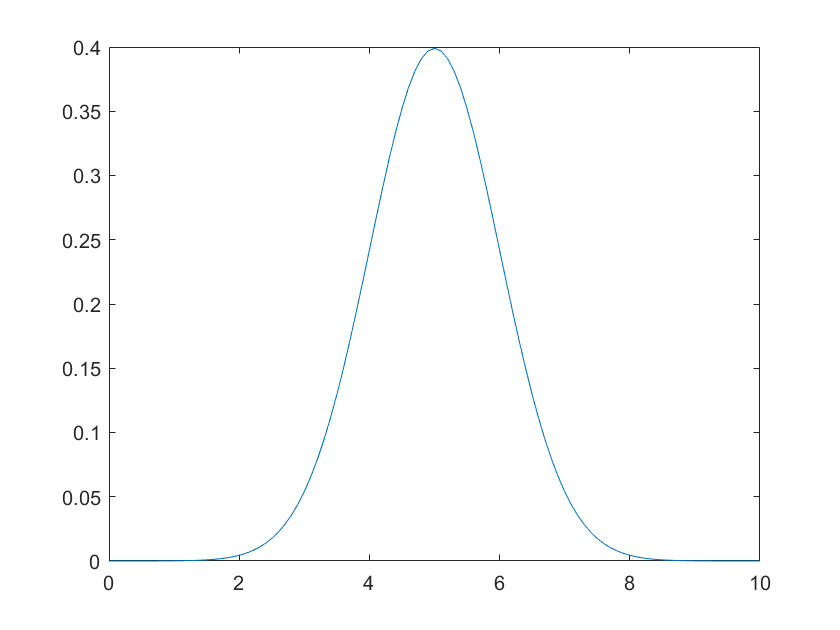

To describe the shape of a specific Normal distribution mathematically, we use a function called the probability density function, $f\left(x\right)$. You might remember meeting this function right back in the very first labs:


$$f\left(x\right)=\frac{1}{\sqrt{2\pi \sigma^2 }}e^{-\frac{{\left(x-\mu \right)}^2 }{2\sigma^2 }}$$


The probability density function lets us control the placement and size of a Normal distribution based on the following two parameters: i) the mean of the distribution ($\mu$), which controls where the bell-shaped curve is centred; ii) the standard deviation of the distribution ($\sigma$), which controls the width of the bell-shaped curve. You can set these values yourself if you want to create a bespoke distribution, but when modelling a real feature you calculate them from the values of the feature in your training data.

Using the values for the mean and standard deviation that you supply, the probability density function will generate, for any possible value of a particular feature, $x$, a new value $f\left(x\right)$. This new value $f\left(x\right)$ is proportional to the probability that the feature value $x$ is generated by the Normal distribution with mean $\mu$ and standard deviation $\sigma$. Even though the probability density function doesn't generate the exact probability, having a value which is proportional to that probability is good enough for many purposes because it allows us to accurately *compare* the probabilities of different feature values. E.g., if the value of the probability density at one point is twice the value at another point then that point is twice as likely to have been generated by the associated Normal distribution. These kinds of comparisons are sufficient for performing classification using Naive Bayes.

So, in order to estimate a probability density function for the distribution of each feature within each class, we would need to:

- Find all the values of the feature in training examples that have a class label matching that class

- Calculate the mean of all those feature values

- Calculate the standard deviation of all those feature values

Let's look at how the `fit()` function handles each of the stages:

First, the `fit()` function finds each of the different possible class labels by calling the `unique()` function on the `train_labels` table:

unique_classes = unique(train_labels)

unique_classes = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


It then works out how many classes there are in total by calling the `length()` function on the result:

n_classes = length(unique_classes)

n_classes = 3

Finally, it loops over all the values in `unique_classes`. Make sure you can identify this loop. Take time to add comments.

Inside each iteration of the loop, it pulls out all of the training examples which belong to the current class using the following logical indexing expression:

% set up the this_class variable as an example:
this_class = unique_classes(1);
% find all the examples from this same class:
examples_from_this_class = train_examples{train_labels==this_class,:}

examples_from_this_class =     4.6000    3.4000    1.4000    0.3000
    5.1000    3.8000    1.5000    0.3000
    4.8000    3.0000    1.4000    0.1000
    4.4000    3.2000    1.3000    0.2000
    5.3000    3.7000    1.5000    0.2000
    4.6000    3.2000    1.4000    0.2000
    4.6000    3.1000    1.5000    0.2000
    4.6000    3.6000    1.0000    0.2000
    5.0000    3.2000    1.2000    0.2000
    5.0000    3.4000    1.5000    0.2000


means = 1×1 cell array
    {1×4 double}


As a reminder, the logical indexing expression essentially says: "give me all of the rows in `train_examples` where the corresponding element of `train_labels` was equal to the value stored inside the `this_class` variable". Remember that the array of class labels for the training data (stored inside `train_labels`) corresponds with the rows of the table containing the training examples. So the first class label corresponds to the example in the first row of the table. The second class label corresponds to the example in the second row of the table. And so on...

(Remember that when we "shuffle" the rows of the dataset to randomise their order, we shuffle it as a single big table that still includes the class labels, and so we don't lose this correspondence. Have another check of the shuffling code in the previous lab if you're not sure.)

Finally, having separated out all the examples from the current class, the loop can then compute the mean and standard deviation for each feature. Remember that we are passing 2D arrays to the `mean()` and `std()` functions and so we will get back arrays of results, containing one value for each feature. The results could be stored as new rows in a big 2D array, but, for ease, the loop writes each new array into its own element of cell array. (Remember you can put *anything* inside an element of a cell array - including another array.)

One cell array is stored in a field of the model structure called `means` (holding the mean values), and one cell array is stored in a field of the model structure called `stds` (holding the standard deviations).

Make sure you can identify the relevant lines of code. Take time to add comments.

## Naive Bayes training: visualising probability densities

Before we leave the Normal probability densities behind, let's have a look at them. It would be interesting to see how well the Normal assumption captures the true distribution of our training data.

First, let's plot the distribution of one feature within one class. In the code below we print out our unique classes as a reminder, select the first one, setosa, and find all the examples from the setosa class, just as we did above:

unique_classes

unique_classes = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


% set up the this_class variable as an example:
this_class = unique_classes(1);
% find all the examples from this same class:
examples_from_this_class = train_examples{train_labels==this_class,:}

examples_from_this_class =     4.6000    3.4000    1.4000    0.3000
    5.1000    3.8000    1.5000    0.3000
    4.8000    3.0000    1.4000    0.1000
    4.4000    3.2000    1.3000    0.2000
    5.3000    3.7000    1.5000    0.2000
    4.6000    3.2000    1.4000    0.2000
    4.6000    3.1000    1.5000    0.2000
    4.6000    3.6000    1.0000    0.2000
    5.0000    3.2000    1.2000    0.2000
    5.0000    3.4000    1.5000    0.2000


Now let's see how the first feature (sepal length) is distributed within examples from that class by plotting a histogram. (A histogram divides a variable up into discrete intervals called "bins" (10 of them by default) and plots how many times the variable fell into each bin):

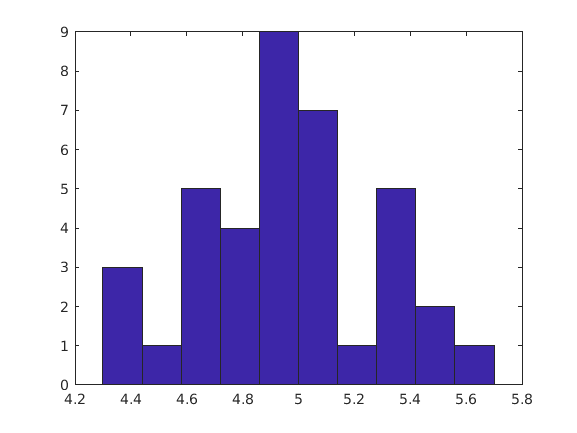

% plot a histogram from the feature stored in the first column
hist(examples_from_this_class(:,1));

Certainly not a perfect bell-shaped curve, but it is broadly symmetric around a high mid-point, with the frequency with which values occurred reducing as we move away from that mid-point. Now let's investigate the Normal distribution we estimated for this feature. The mean and standard deviations for the distribution of the first feature within examples from the first class will be stored in the first element of the array in the first cell of the `means` cell array, and the first element of the array in the first cell of the `stds` array. If you're not sure why then revisit the loop inside the `fit()` function which we examined in the previous section. Let's read the values out of our model structure and have a look:

my_m.means{1}(1)

ans = 4.9737

my_m.stds{1}(1)

ans = 0.3367

Now let's make another plot, overlaying the Normal distribution described by this mean and standard deviation onto our histogram so we can see how well it "fits". You might remember from the very first lab that Matlab has a function that will give us the value of a Normal probability density function with a particular mean and standard deviation at any given point. Let's try it with a random example. If we have a Normal distribution with a mean of -2 and a standard deviation of 3 then what is the probability density at a value of -2.5:

density = normpdf(-2.5, -2, 3)

density = 0.1311

We can also ask about the probability density at a whole set of different points: an array. Let's sample the density over the range -5 to +1 in jumps of 0.1:

densities = normpdf(-5:0.1:1, -2, 3)

densities =     0.0807    0.0833    0.0860    0.0887    0.0913    0.0940    0.0966    0.0991    0.1016    0.1041    0.1065    0.1088    0.1111    0.1133    0.1154    0.1174    0.1193    0.1211    0.1228    0.1243    0.1258    0.1271    0.1283    0.1294    0.1303    0.1311    0.1318    0.1323    0.1327    0.1329    0.1330    0.1329    0.1327    0.1323    0.1318    0.1311    0.1303    0.1294    0.1283    0.1271    0.1258    0.1243    0.1228    0.1211    0.1193    0.1174    0.1154    0.1133    0.1111    0.1088


And let's plot the densities out using a bar chart to check we see the bell-shaped curve we expect:

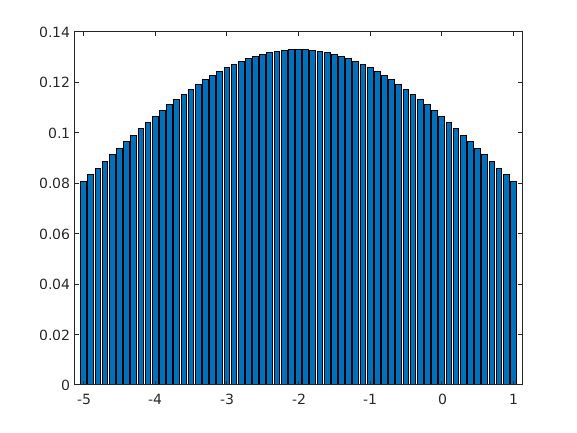

bar(-5:0.1:1, densities)

Now we understand how to visualise the probability density function for a Normal distribution, let's plug in the values we estimated from the training data and overlay the distribution onto our original histogram.

Before we can do this we have a problem to address. Remember a value of the Normal probability density function isn't meaningful by itself: for a particular feature value, the function will only provide us with a number which is *proportional* to the probability of observing that value. What matters is the overall *shape* of the function, and that we can use it to accurately *compare* different values. Similarly, the size of the numbers in each histogram bin aren't meaningful by themselves. If we had had lots more training examples from this class then the number of examples in the bins would be higher, but their *relative* sizes wouldn't change. We could go on adding more and more measurements from setosa irises for as long as we wanted and, though the numbers on the y-axis would grow larger, broadly speaking the shape of the histogram wouldn't change. Again, what matters is the overall *shape* of the histogram, not how many examples we happen to have.

So to plot our probability density function and out histogram together on the same graph and compare their shapes, we'll have to take some simple steps to re-scale them so that their values on the y-axis are at least similar. In the following code we do this by scaling the probability density function up so that its maximum value is equal to the maximum bin value in our histogram (which is 9):

% plot a histogram from the feature stored in the first column
hist(examples_from_this_class(:,1));
% sample the densities across the approximate range spanned by our histogram
% in jumps of 0.1:
x = 4.2:0.1:5.8;
y = normpdf(x, my_m.means{1}(1), my_m.stds{1}(1));
% scale the densities up so that the maximim value matches our maximum bin:
y = y .* (9 / max(y));
% overlay the densities (this time as a line graph, so we can see both results:
hold('on');
plot(x,y,'-x');

The Normal distribution gives a pretty good approximation to the true underlying distribution of this feature within this class. Normal distributions are commonly used as an approximation throughout machine learning. Often the level of fit between the approximation and the data is much worse than one we see here for our setosa sepal lengths, but the approximation is "good enough" that we can still get good performance from our machine learning algorithm.

Before we move on, let's have a look at another example. How about the distribution of petal lengths for the versicolor class:

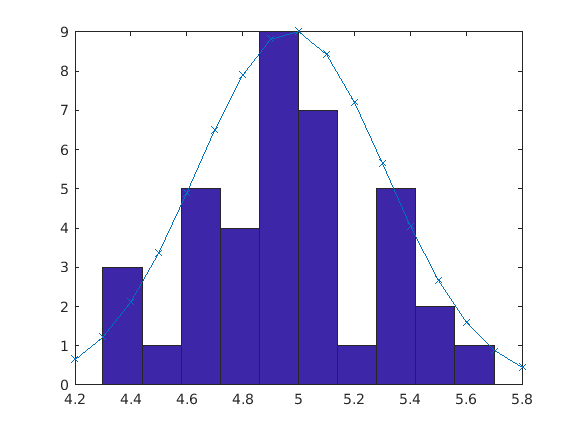

hold('off');

% set up the this_class variable as an example:
this_class = unique_classes(2);
% find all the examples from this same class:
examples_from_this_class = train_examples{train_labels==this_class,:}

examples_from_this_class =     6.9000    3.1000    4.9000    1.5000
    5.7000    3.0000    4.2000    1.2000
    5.5000    2.3000    4.0000    1.3000
    5.4000    3.0000    4.5000    1.5000
    6.7000    3.0000    5.0000    1.7000
    6.0000    2.7000    5.1000    1.6000
    6.4000    2.9000    4.3000    1.3000
    5.6000    2.7000    4.2000    1.3000
    5.9000    3.0000    4.2000    1.5000
    6.1000    2.9000    4.7000    1.4000


% plot a histogram from the feature stored in the third column:
hist(examples_from_this_class(:,3));
% sample the densities across the approximate range spanned by our histogram
% in jumps of 0.1:
x = 3:0.1:5.5;
y = normpdf(x, my_m.means{2}(3), my_m.stds{2}(3));
% scale the densities up so that the maximim value matches our maximum bin:
y = y .* (8 / max(y));
% overlay the densities (this time as a line graph, so we can see both results:
hold('on');
plot(x,y,'-x');

Before you move on, try copying, pasting and editing the code to look at the distribution of petal widths for the virginica class and how well the Normal distribution we estimated approximates it:

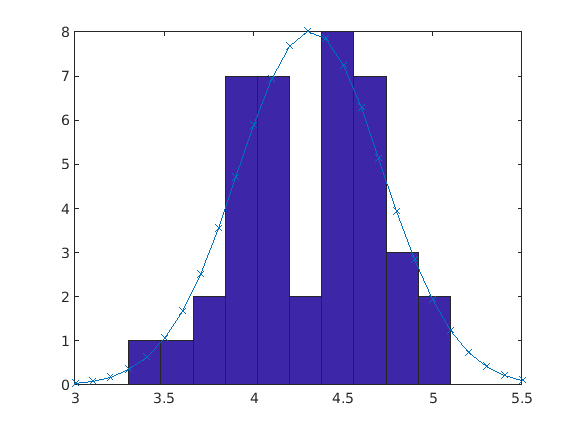

% add your code below:
hold('off');

% set up the this_class variable as an example:
this_class = unique_classes(3);
% find all the examples from this same class:
examples_from_this_class = train_examples{train_labels==this_class,:}

examples_from_this_class =     6.3000    2.5000    5.0000    1.9000
    7.7000    3.0000    6.1000    2.3000
    6.3000    2.7000    4.9000    1.8000
    7.2000    3.0000    5.8000    1.6000
    6.3000    3.3000    6.0000    2.5000
    6.3000    2.9000    5.6000    1.8000
    6.4000    3.1000    5.5000    1.8000
    5.8000    2.7000    5.1000    1.9000
    7.2000    3.2000    6.0000    1.8000
    6.2000    2.8000    4.8000    1.8000


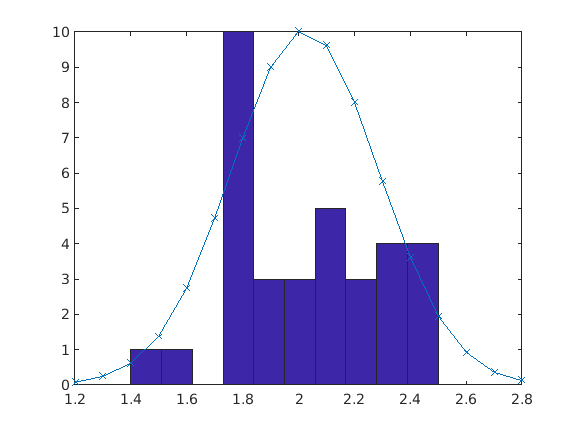

% plot a histogram from the feature stored in the third column:
hist(examples_from_this_class(:,4));
% sample the densities across the approximate range spanned by our histogram
% in jumps of 0.1:
x = 1.2:0.1:2.8;
y = normpdf(x, my_m.means{3}(4), my_m.stds{3}(4));
% scale the densities up so that the maximim value matches our maximum bin:
y = y .* (10 / max(y));
% overlay the densities (this time as a line graph, so we can see both results:
hold('on');
plot(x,y,'-x');

## Naive Bayes training: estimating a prior

The second step we need to focus on is that the `fit()` function makes an estimate of how likely each class label is to occur, based on how many times it is present in the training data. This probability is called a prior.

The `fit()` function calculates the prior by making a second loop over all the values in `unique_classes`.

Inside each iteration of the loop, it pulls out all of the training examples which belong to the current class using the same logical indexing expression we met in the previous sections:

% set up the this_class variable as an example:
this_class = unique_classes(1);
% find all the examples from this same class:
examples_from_this_class = train_examples{train_labels==this_class,:}

examples_from_this_class =     4.6000    3.4000    1.4000    0.3000
    5.1000    3.8000    1.5000    0.3000
    4.8000    3.0000    1.4000    0.1000
    4.4000    3.2000    1.3000    0.2000
    5.3000    3.7000    1.5000    0.2000
    4.6000    3.2000    1.4000    0.2000
    4.6000    3.1000    1.5000    0.2000
    4.6000    3.6000    1.0000    0.2000
    5.0000    3.2000    1.2000    0.2000
    5.0000    3.4000    1.5000    0.2000


It then calculates the number of examples from the current class as a fraction of the total number of training examples, to give a probability approximating the likelihood that a randomly chosen iris will belong to this class:

size(examples_from_this_class,1) / size(train_labels,1)

ans = 0.3393

Make sure you can identify the line where this calculation happens and you're happy about where the results of the calculation are being stored. Take time to add comments.

## Naive Bayes prediction: overview

The `predict()` function in the mynb class is responsible for performing all the steps involved in prediction. Let's call it again:

% use our model to classify the testing dataset:
my_predictions = mynb.predict(my_m, test_examples);

classifying example 1/38
classifying example 2/38
classifying example 3/38
classifying example 4/38
classifying example 5/38
classifying example 6/38
classifying example 7/38
classifying example 8/38
classifying example 9/38
classifying example 10/38
classifying example 11/38
classifying example 12/38
classifying example 13/38
classifying example 14/38
classifying example 15/38
classifying example 16/38
classifying example 17/38
classifying example 18/38
classifying example 19/38
classifying example 20/38
classifying example 21/38
classifying example 22/38
classifying example 23/38
classifying example 24/38
classifying example 25/38
classifying example 26/38
classifying example 27/38
classifying example 28/38
classifying example 29/38
classifying example 30/38
classifying example 31/38
classifying example 32/38
classifying example 33/38
classifying example 34/38
classifying example 35/38
classifying example 36/38
classifying example 37/38
classifying example 38/38


Have a look at the mynb class and make sure you can find the `predict()` function.

Here are the important steps that take place during prediction with the Naive Bayes algorithm. After each one, in brackets, is a rough indication of how complicated that step is to understand, e.g. "easy", "moderately hard", etc:

Prediction

- Compute a likelihood given each class, for the new example we are trying to classify (moderately hard)

- Multiply each likelihood by the prior for the corresponding class to give a value proportional to the posterior probability (easy)

- Generate a prediction of the class label by finding the class with the largest resulting value (easy)

In the following sections we work through each of steps in greater detail, looking at the corresponding lines of code in the mynb class. You should make sure you have the mynb class open ready to read and add your comments to, and you should make sure you look after your copy of the file carefully in between now and the in-class test.

## Naive Bayes prediction: one example at a time

The first thing to notice is that the `predict()` function itself doesn't really do all that much...

The `predict()` function has been written to mimic the built-in Matlab function with the same name and it will accept as many different test examples as you want to want to pass it all bundled together in a single big table (the second argument of the function).

All it then does is to loop through all of the test examples in the table and call the `predict_one()` function on each one. Remember there's one example per row in our tables, so to loop over the number of examples, we'd need to find the height of the table. We can get this with a call to `size(test_examples, 1)` and you should be able to identify the point where this call happens. You should also be able to identify the line of code that extracts a single example from the table, the line that passes it to `predict_one()`, and what happens to the result returned by `predict_one()`. Take time to add comments.

The next section moves on to look at the `predict_one()` function in more detail.

## Naive Bayes prediction: computing likelihoods

The `predict_one()` function loops over all the possible class labels and, for each one, calculates a likelihood for the current test example given the class. It does this by calling the `calculate_likelihood()` function.

The `calculate_likelihood()` function works by considering the value of every feature in the current test example, in isolation. This is the class-conditional independence assumption of Naive Bayes in action. We treat the observed value of each feature as an independent event, then look at how likely it was to occur given the probability density function we estimated from the distribution of this feature in examples belonging to this class, and multiply each of the answers we get (one per feature) together to produce a single estimate of the likelihood of the example given the class. The Naive Bayes approach can't capture dependent relationships within the training data. For example, if setosa irises with large petal lengths tend also to have large petal widths, and setosa irises with small petal lengths tend also to have small petal widths. This relationship *between* the two features will be lost. We consider the value of each feature in complete isolation, and we model each of the feature distributions using its own Normal probability density function with its own mean and standard deviation. Though quite simplistic, the class-conditional independence assumption made by Naive Bayes can still prove very effective in terms of overall performance.

To calculate the likelihood of each feature value we need to look at the probability density function we calculated for the current class during training. Remember that we are using a Normal probability density function, and that it is controlled by two values: its mean and its standard deviation. Remember from the visualisation work we did above that the mean for the distribution of the first feature across examples from the first class will be stored in the first element of the array in the first cell of the `means` array, and its standard deviation will be stored in the first element of the array in the first cell of the `stds` array. (Revisit the loop inside the `fit()` function if you're not sure why.)

Let's have a look at the first test example and work through some of the steps:

this_test_example = test_examples{1,:}

this_test_example =     4.7000    3.2000    1.3000    0.2000


Let's look at calculating the likelihood of this example conditioned on the first class (setosa). For the first feature in this example, we could calculate the probability density with a call to the built-in Matlab function `normpdf()`, as follows:

density_1 = normpdf(this_test_example(1), my_m.means{1}(1), my_m.stds{1}(1))

density_1 = 0.8516

We could then repeat this step to calculate the probability density for the second feature:

density_2 = normpdf(this_test_example(2), my_m.means{1}(2), my_m.stds{1}(2))

density_2 = 0.8810

And so on...

You should be able to identify a loop in the `calculate_likelihood()` function that calculates these densities for every feature value. You will notice that it isn't calling the `normpdf()` function, but the mynb class's own `calculate_pd()` function. More on this shortly, but for now check you're happy with the loop and the fact it's simply multiplying together probability densities for each feature in the example. Take time to add comments.

The mynb class aims to avoid relying on any built-in Matlab functions and implement the classifier from scratch to ensure we have a full understanding of all the steps. For this reason it includes its own function for calculating a probability density at a given value given a Normal distribution with a particular mean and standard deviation. This is the mathematical function we discussed in detail during the analysis of the training phase:


$$f\left(x\right)=\frac{1}{\sqrt{2\pi \sigma^2 }}e^{-\frac{{\left(x-\mu \right)}^2 }{2\sigma^2 }}$$


The probability density function is implemented by the function `calculate_pd()`. Make sure you can find the function and you are happy with how it implements the formula. Take time to add comments. (Remember we previously worked through this function in the Matlab Fundamentals material and you may wish to refer back to it.)

Let's use the `calculate_pd()` function to calculate the same two densities we calculated above, and check the results agree with the results we got from `normpdf()`:

mynb.calculate_pd(this_test_example(1), my_m.means{1}(1), my_m.stds{1}(1))

ans = 0.8516

mynb.calculate_pd(this_test_example(2), my_m.means{1}(2), my_m.stds{1}(2))

ans = 0.8810

## Naive Bayes prediction: approximating the posterior

Now returning to the `predict_one()` function... The `predict_one()` function loops over all the possible class labels and, for each one, calculates a likelihood for the current test example given the class (covered in the previous section). It then computes a value which is proportional to the posterior: the probability of the current class label, given the test example. It does this by multiplying the likelihood it has just calculated with the prior for the current class.

The prior for the current class is something that is calculated by the `fit()` function during training and which we covered in the earlier analysis of the training phase. The prior for any given class is calculated as the number of training examples belonging to that class divided by the total number of training examples.

The function `get_prior()` is used to fetch the prior for the current class. It's nice and simple, just reading the probability from the model structure. Make sure you can find the line where the function is called, and the function itself. Take time to add comments.

Let's perform the same steps as the `predict_one()` function for the first test example, displaying the prior for each class as we loop:

this_test_example = test_examples{1,:}

this_test_example =     4.7000    3.2000    1.3000    0.2000


posterior_ = [];

for i=1:my_m.n_classes
    this_likelihood = mynb.calculate_likelihood(my_m, this_test_example, i);
    this_prior = mynb.get_prior(my_m, i)
    posterior_(i) = this_likelihood * this_prior
end

this_prior = 0.3393

posterior_ = 1.3672

this_prior = 0.3571

posterior_ =     1.3672    0.0000


this_prior = 0.3036

posterior_ =     1.3672    0.0000    0.0000


## Naive Bayes prediction: generating a prediction

Now returning to the `predict_one()` function... The function `predict_one()` calculates numbers which approximate the true posterior probabilities for each class (see the previous section) and this is reflected in the naming of the array that holds them: `posterior_`. However, the values in `posterior_` are guaranteed to be proportional to the true posterior probabilities, and we can reliably select the most likely class label by finding the maximum value in the array.

The built-in Matlab function `max()` can help us with this job, but we have to be a bit careful as it returns the value of the maximum value in the array. What we're really interested in is the index of the array element containing the maximum value, because this tells us which element of `unique_classes` to look in for the name of the predicted class label. We can get this index by asking for the second return value of the `max()` function:

[winning_value_, winning_index] = max(posterior_)

winning_value_ = 1.3672

winning_index = 1

prediction = my_m.unique_classes(winning_index)

prediction = categorical
     setosa 


Make sure you can find the equivalent lines in the `predict_one()` function. Take time to add comments.

## Tasks

Review your copy of the mynb class and check you are happy with the overall standard of the commenting:

- If you forget a detail about Naive Bayes classification while taking the 1CWK50 Moodle quiz, are your comments good enough to help you figure it out?

- Have you commented each line of code? (Or some comments adequately cover multiple lines of code)

- Have you included overview comments above each of the functions?

- Have you focused on the *why* rather than the *what*? (see also the "Writing good comments" document on Moodle)

- When you're happy, upload your commented mynb class to the 1CWK50 component 1 submission box - you can update your submission as many times as you want between now and the deadline